# Proyecto Final

Obtiene todas las imágenes de cada clase del directorio *Objetos_segmentados*

[imageClasses,labelMap] = ImageProcessing.getImagesClasses("Objetos_segmentados");

Se muestra la imagen 3 de la segunda clase

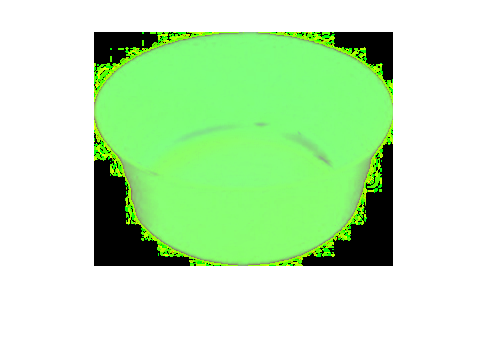

imshow(rgb2hsv(imageClasses{2}{3}))

Se muestran las propiedades de labelMap y un ejemplo de su uso

labelMap

labelMap =   Map with properties:

        Count: 10
      KeyType: double
    ValueType: char


fprintf('A la clase %d le pertence la etiqueta %s',1,labelMap(1));

A la clase 1 le pertence la etiqueta appleJuice

Divide a las imágenes en datos de entreneamiento y datos de prueba

images_train = cellfun(@(imageClass) imageClass(1:15), imageClasses, 'UniformOutput', false);
images_test = cellfun(@(imageClass) imageClass(16:end), imageClasses, 'UniformOutput', false);

images_train_HSV = cellfun(@rgb2hsv, images_train{2}, 'UniformOutput', false)

images_train_HSV = 1×15 cell array
    {318×385×3 double}    {270×345×3 double}    {234×299×3 double}    {320×394×3 double}    {310×368×3 double}    {286×331×3 double}    {292×338×3 double}    {304×350×3 double}    {240×294×3 double}    {228×288×3 double}    {227×276×3 double}    {361×570×3 double}    {275×305×3 double}    {248×388×3 double}    {318×475×3 double}


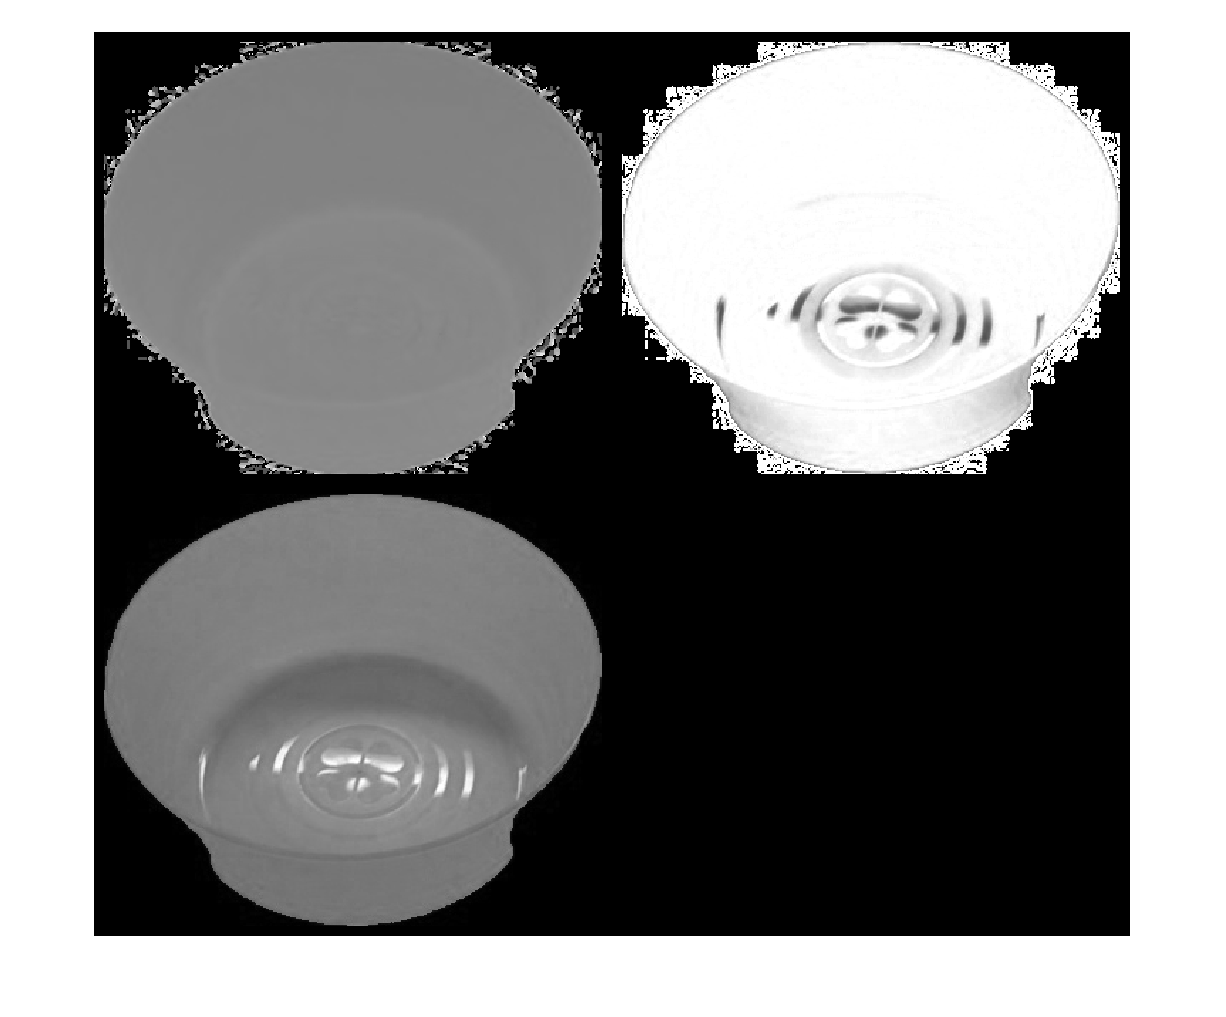

[h s v] = imsplit(images_train_HSV{8});
montage({h, s, v}, 'BorderSize', 10);

Para cada clase de imagenes se obtiene su cuantizador vectorial

sizeQuantizer = 16; % Tamaño de los cuantizadores vectoriales
vecQuantizers = {}; % Cell array para almacenar a los cuantizadores vectoriales
for i = 1:length(images_train)
  images_train_HSV = cellfun(@rgb2hsv, images_train{i}, 'UniformOutput', false);
  pixels = ImageProcessing.imgClass2matrix(images_train_HSV);
  C1 = 1/length(pixels) *sum(pixels);
  [idx, C] = CuantizadorVectorial.LindeBuzoGray(C1,sizeQuantizer,double(pixels));
  vecQuantizers{i} = {idx, C};
end

Se verifican los centroides obtenidos, así como la cantidad de elementos que contiene cada grupo en el cuantizador vectorial de la clase appleJuice.

idx_1 = vecQuantizers{1}{1}; %Índices asignados a cada pixel de la clase appleJuice
C_1 = vecQuantizers{1}{2} %Centroides del cuantizador de la clase appleJuice

C_1 =

    0.0025    0.0021    0.0037
    0.4940    0.2281    0.5261
    0.1321    0.0953    0.5524
    0.3445    0.9901    0.0068
    0.0233    0.5967    0.5072
    0.8430    0.2687    0.2953
    0.4595    0.4366    0.4285
    0.9571    0.5187    0.3784
    0.0772    0.3440    0.4198
    0.5785    0.0986    0.5910
    0.0932    0.1179    0.7943
    0.7364    0.9612    0.0328
    0.0108    0.9931    0.0228
    0.8993    0.1389    0.5498
    0.4383    0.7591    0.4616
    0.9711    0.7414    0.3577



for i=1:sizeQuantizer
  fprintf('Centroide: %d  Elementos: %d\n',i,numel(find(idx_1 == i)))
end

Centroide: 1  Elementos: 119691
Centroide: 2  Elementos: 159185
Centroide: 3  Elementos: 72029
Centroide: 4  Elementos: 18349
Centroide: 5  Elementos: 64838
Centroide: 6  Elementos: 54342
Centroide: 7  Elementos: 91369
Centroide: 8  Elementos: 103831
Centroide: 9  Elementos: 55024
Centroide: 10  Elementos: 124371
Centroide: 11  Elementos: 15426
Centroide: 12  Elementos: 32972
Centroide: 13  Elementos: 26995
Centroide: 14  Elementos: 64606
Centroide: 15  Elementos: 43881
Centroide: 16  Elementos: 157123


Clasificación de las imagenes de entrenamiento

disp('Clasificando las imágenes de entrenamiento')

Clasificando las imágenes de entrenamiento


La clasificación para las imágenes de la clase 1 (appleJuice) fue:
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1

La clasificación para las imágenes de la clase 2 (blueBowl) fue:
     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2

La clasificación para las imágenes de la clase 3 (blueLego) fue:
     3     3     3     2     3     3     3     5     2     3     3     3     3     3     3

La clasificación para las imágenes de la clase 4 (blueMug) fue:
     4     4     4     3     4     4     4     4     4     4     4     4     4     4     4

La clasificación para las imágenes de la clase 5 (blueSpoon) fue:
     2     2     2     2     2     2     2     5     5     5     5     5     5     5     5

La clasificación para las imágenes de la clase 6 (chocolateCookies) fue:
     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6

La clasificación para las imágenes de la clase 7

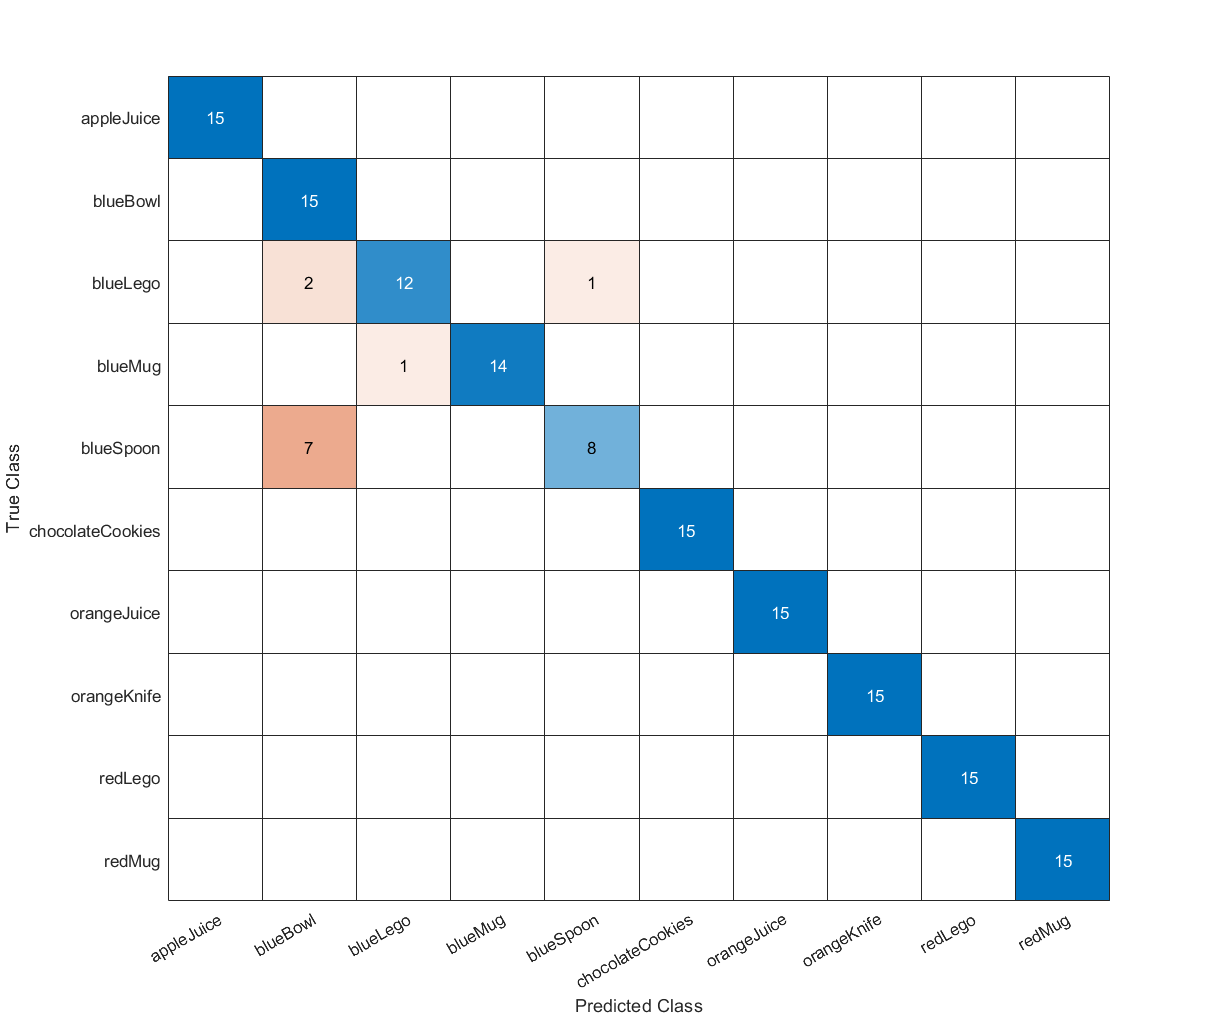

clasificacionCuantVect(images_train,vecQuantizers,labelMap)

Clasificación de las imagenes de prueba

disp('Clasificando las imágenes de prueba')

Clasificando las imágenes de prueba


La clasificación para las imágenes de la clase 1 (appleJuice) fue:
     1     1     1     1     1

La clasificación para las imágenes de la clase 2 (blueBowl) fue:
     2     2     2     2     2

La clasificación para las imágenes de la clase 3 (blueLego) fue:
     3     3     3     3     3

La clasificación para las imágenes de la clase 4 (blueMug) fue:
     4     4     3     3     4

La clasificación para las imágenes de la clase 5 (blueSpoon) fue:
     5     2     2     3     3

La clasificación para las imágenes de la clase 6 (chocolateCookies) fue:
     6     6     6     6     6

La clasificación para las imágenes de la clase 7 (orangeJuice) fue:
     7     7     7     7     7

La clasificación para las imágenes de la clase 8 (orangeKnife) fue:
     8     8     8     8     8

La clasificación para las imágenes de la clase 9 (redLego) fue:
     9     9     9     9     9

La clasificación para las imágenes de la clase 10 (redMug) fue:
    10    10    10    10    10



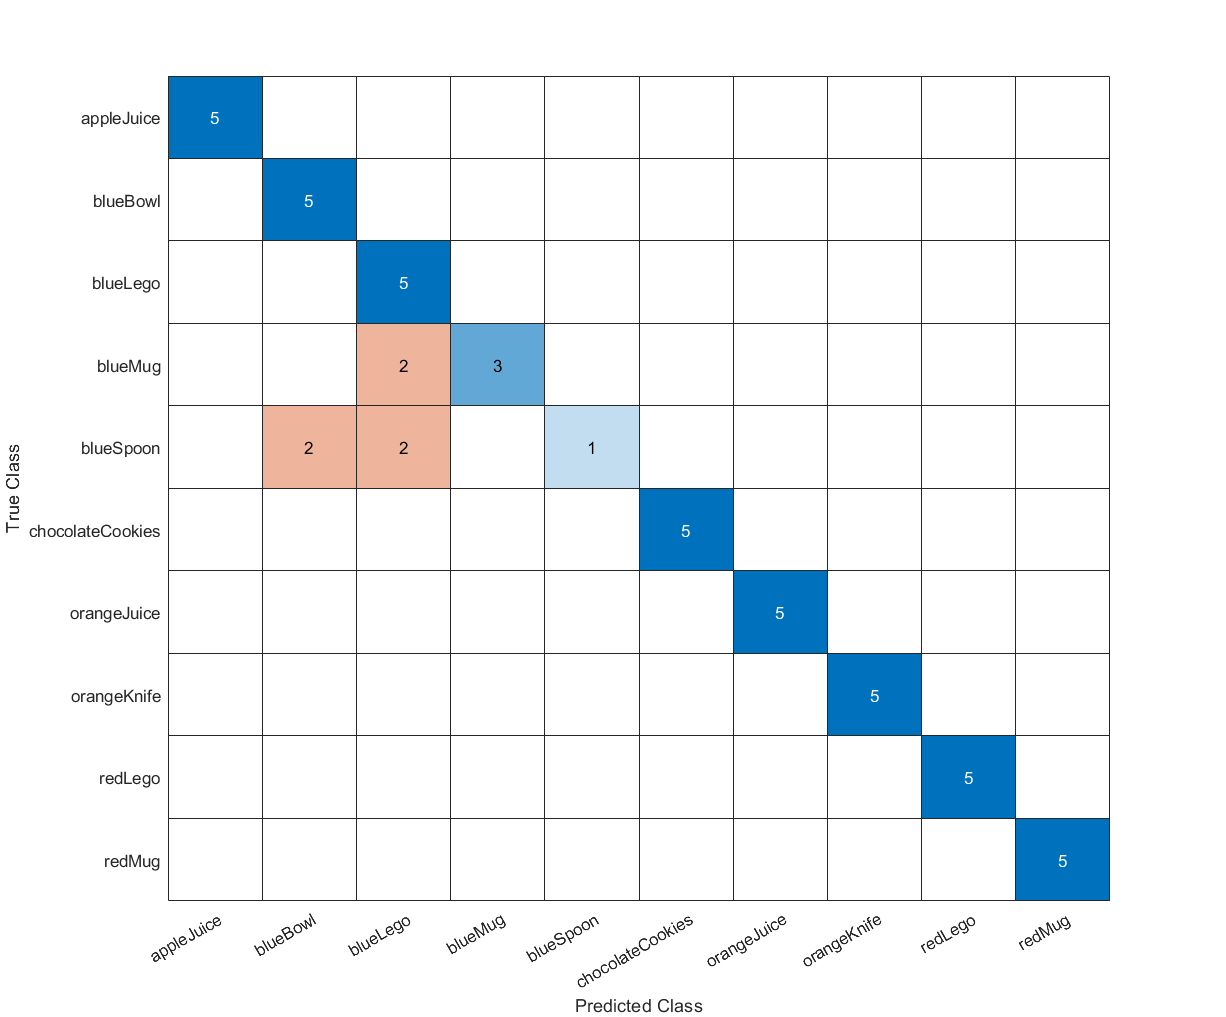

clasificacionCuantVect(images_test,vecQuantizers,labelMap)

**Clasificación de imágenes mediante cuantización vectorial**

Función para clasificar las imagenes, ya sea de entrenamiento o de prueba mediante la tecnica de cuantización vectorial.

Al final muestra su matriz de confusión.

function clasificacionCuantVect(imgClass,quantizers,labelMap)
  prediction = double.empty; % Valores que el clasificador predice
  actual = double.empty; % Valores reales
  for i=1:length(imgClass) % Itera sobre las clases
    nImgs = length(imgClass{i});
    clasifications = zeros(1,nImgs);
    for j=1:nImgs % Itera sobre las imágenes de la clase iésima
      % Obtiene los pixeles de la imagen
      pixels = ImageProcessing.img2matrix(rgb2hsv(imgClass{i}{j}));
      % Obtiene la clasificación de la imagen de acuerdo a su distancia
      % mínima a cada cuantizador
      clasifications(j) = CuantizadorVectorial.clasificador(double(pixels),quantizers);
    end
    prediction = [prediction,clasifications];
    actual = [actual,ones(1,nImgs)*i];
    fprintf('La clasificación para las imágenes de la clase %d (%s) fue:\n',i,labelMap(i));
    disp(clasifications)
  end
  % Obtiene las etiquetas de los valores reales y predichos
  labelActual = arrayfun(@(num) labelMap(num),actual,'UniformOutput',false);
  labelPred = arrayfun(@(num) labelMap(num),prediction,'UniformOutput',false);
  % Genera una matriz de confusión y las muestra
  confusionchart(labelActual,labelPred)
end